clc;
clear;
close all;

videoFile = "C:\Users\23775\Desktop\zhaos.mp4";
videoObj = VideoReader(videoFile);

frameFolder = fullfile(tempdir, "video_frames");
if ~exist(frameFolder, "dir")
    mkdir(frameFolder);
end

frameIdx = 0;
framePaths = {};
while hasFrame(videoObj)
    frame = readFrame(videoObj);
    frameIdx = frameIdx + 1;
    frameFile = fullfile(frameFolder, sprintf("frame_%04d.png", frameIdx));
    imwrite(frame, frameFile);
    framePaths{end+1} = frameFile;  
end

framePaths = string(framePaths);  
framePaths = framePaths(isfile(framePaths));  
if isempty(framePaths)
    error('未成功生成任何有效图像帧，请检查视频文件。');
end
imds = imageDatastore(framePaths);


currFrameIdx = 1;
currI = readimage(imds, currFrameIdx);
himage = imshow(currI);
rng(0);  

% Create a cameraIntrinsics object to store the camera intrinsic parameters.
% The intrinsics for the dataset can be found at the following page:
% https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
% Note that the images in the dataset are already undistorted, hence there
% is no need to specify the distortion coefficients.
focalLength    = [535.4, 539.2];    % in units of pixels
principalPoint = [320.1, 247.6];    % in units of pixels
imageSize      = size(currI,[1 2]);  % in units of pixels
intrinsics     = cameraIntrinsics(focalLength, principalPoint, imageSize);

% Detect and extract ORB features
scaleFactor = 1.2;
numLevels   = 8;
numPoints   = 1000;
[preFeatures, prePoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints); 

currFrameIdx = currFrameIdx + 1;
firstI       = currI; % Preserve the first frame 

isMapInitialized  = false;

% Map initialization loop
while ~isMapInitialized && currFrameIdx < numel(imds.Files)
    currI = readimage(imds, currFrameIdx);

    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints); 

    currFrameIdx = currFrameIdx + 1;

    % Find putative feature matches
    indexPairs = matchFeatures(preFeatures, currFeatures, Unique=true, ...
        MaxRatio=0.9, MatchThreshold=40);

    % If not enough matches are found, check the next frame
    minMatches = 100;
    if size(indexPairs, 1) < minMatches
        continue
    end

    preMatchedPoints  = prePoints(indexPairs(:,1),:);
    currMatchedPoints = currPoints(indexPairs(:,2),:);

    % Compute homography and evaluate reconstruction
    [tformH, scoreH, inliersIdxH] = helperComputeHomography(preMatchedPoints, currMatchedPoints);

    % Compute fundamental matrix and evaluate reconstruction
    [tformF, scoreF, inliersIdxF] = helperComputeFundamentalMatrix(preMatchedPoints, currMatchedPoints, intrinsics);

    % Select the model based on a heuristic
    ratio = scoreH/(scoreH + scoreF);
    ratioThreshold = 0.45;
    if ratio > ratioThreshold
        inlierTformIdx = inliersIdxH;
        tform          = tformH;
    else
        inlierTformIdx = inliersIdxF;
        tform          = tformF;
    end

    % Computes the camera location up to scale. Use half of the 
    % points to reduce computation
    inlierPrePoints  = preMatchedPoints(inlierTformIdx);
    inlierCurrPoints = currMatchedPoints(inlierTformIdx);
    [relPose, validFraction] = estrelpose(tform, intrinsics, ...
        inlierPrePoints(1:2:end), inlierCurrPoints(1:2:end));

    % If not enough inliers are found, move to the next frame
    if validFraction < 0.9 || numel(relPose)>1
        continue
    end

    % Triangulate two views to obtain 3-D map points
    minParallax = 1; % In degrees
    [isValid, xyzWorldPoints, inlierTriangulationIdx] = helperTriangulateTwoFrames(...
        rigidtform3d, relPose, inlierPrePoints, inlierCurrPoints, intrinsics, minParallax);

    if ~isValid
        continue
    end

    % Get the original index of features in the two key frames
    indexPairs = indexPairs(inlierTformIdx(inlierTriangulationIdx),:);

    isMapInitialized = true;

    disp(['Map initialized with frame 1 and frame ', num2str(currFrameIdx-1)])
end % End of map initialization loop

Map initialized with frame 1 and frame 14


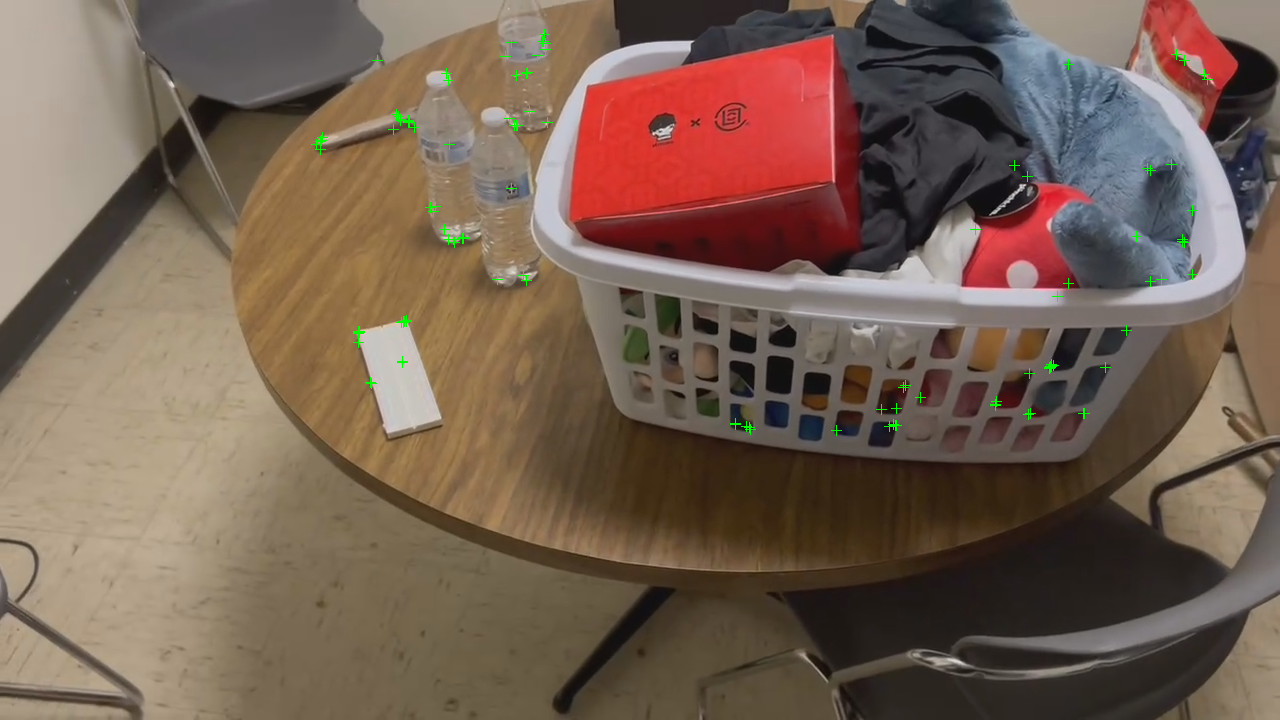


if isMapInitialized
    close(himage.Parent.Parent); % Close the previous figure
    % Show matched features
    hfeature = showMatchedFeatures(firstI, currI, prePoints(indexPairs(:,1)), ...
        currPoints(indexPairs(:, 2)), "Montage");
else
    error('Unable to initialize the map.')
end

% Create an empty imageviewset object to store key frames
vSetKeyFrames = imageviewset;

% Create an empty worldpointset object to store 3-D map points
mapPointSet   = worldpointset;

% Add the first key frame. Place the camera associated with the first 
% key frame at the origin, oriented along the Z-axis
preViewId     = 1;
vSetKeyFrames = addView(vSetKeyFrames, preViewId, rigidtform3d, Points=prePoints,...
    Features=preFeatures.Features);

% Add the second key frame
currViewId    = 2;
vSetKeyFrames = addView(vSetKeyFrames, currViewId, relPose, Points=currPoints,...
    Features=currFeatures.Features);

% Add connection between the first and the second key frame
vSetKeyFrames = addConnection(vSetKeyFrames, preViewId, currViewId, relPose, Matches=indexPairs);

% Add 3-D map points
[mapPointSet, newPointIdx] = addWorldPoints(mapPointSet, xyzWorldPoints);

% Add image points corresponding to the map points in the first key frame
mapPointSet   = addCorrespondences(mapPointSet, preViewId, newPointIdx, indexPairs(:,1));

% Add image points corresponding to the map points in the second key frame
mapPointSet   = addCorrespondences(mapPointSet, currViewId, newPointIdx, indexPairs(:,2));


% Load the bag of features data created offline
bag         = bagOfFeaturesDBoW("bagOfFeatures.bin.gz");

% Initialize the place recognition database
loopDatabase    = dbowLoopDetector(bag);

% Add features of the first two key frames to the database
addVisualFeatures(loopDatabase, preViewId, preFeatures);
addVisualFeatures(loopDatabase, currViewId, currFeatures);

% Run full bundle adjustment on the first two key frames
tracks       = findTracks(vSetKeyFrames);
cameraPoses  = poses(vSetKeyFrames);

[refinedPoints, refinedAbsPoses] = bundleAdjustment(xyzWorldPoints, tracks, ...
    cameraPoses, intrinsics, FixedViewIDs=1, ...
    PointsUndistorted=true, AbsoluteTolerance=1e-7,...
    RelativeTolerance=1e-15, MaxIteration=20, ...
    Solver="preconditioned-conjugate-gradient");

% Scale the map and the camera pose using the median depth of map points
medianDepth   = median(vecnorm(refinedPoints.'));
refinedPoints = refinedPoints / medianDepth;

refinedAbsPoses.AbsolutePose(currViewId).Translation = ...
    refinedAbsPoses.AbsolutePose(currViewId).Translation / medianDepth;
relPose.Translation = relPose.Translation/medianDepth;

% Update key frames with the refined poses
vSetKeyFrames = updateView(vSetKeyFrames, refinedAbsPoses);
vSetKeyFrames = updateConnection(vSetKeyFrames, preViewId, currViewId, relPose);

% Update map points with the refined positions
mapPointSet = updateWorldPoints(mapPointSet, newPointIdx, refinedPoints);

% Update view direction and depth 
mapPointSet = updateLimitsAndDirection(mapPointSet, newPointIdx, vSetKeyFrames.Views);

% Update representative view
mapPointSet = updateRepresentativeView(mapPointSet, newPointIdx, vSetKeyFrames.Views);

% Visualize matched features in the current frame
close(hfeature.Parent.Parent);
featurePlot   = helperVisualizeMatchedFeatures(currI, currPoints(indexPairs(:,2)));

% Visualize initial map points and camera trajectory
mapPlot       = helperVisualizeMotionAndStructure(vSetKeyFrames, mapPointSet);

% Show legend
showLegend(mapPlot);

% ViewId of the current key frame
currKeyFrameId   = currViewId;

% ViewId of the last key frame
lastKeyFrameId   = currViewId;

% Index of the last key frame in the input image sequence
lastKeyFrameIdx  = currFrameIdx - 1; 

% Indices of all the key frames in the input image sequence
addedFramesIdx   = [1; lastKeyFrameIdx];

isLoopClosed     = false;

% Main loop
isLastFrameKeyFrame = true;

% Create and initialize the KLT tracker
tracker = vision.PointTracker(MaxBidirectionalError = 5);
initialize(tracker, currPoints.Location(indexPairs(:,2), :), currI);

while currFrameIdx < numel(imds.Files)  
    currI = readimage(imds, currFrameIdx);
    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI, scaleFactor, numLevels, numPoints);

    % Track the last key frame
    [currPose, mapPointsIdx, featureIdx] = helperTrackLastKeyFrameKLT(tracker, currI, mapPointSet, ...
        vSetKeyFrames.Views, currFeatures, currPoints, lastKeyFrameId, intrinsics);

    % Track the local map and check if the current frame is a key frame.
    % A frame is a key frame if both of the following conditions are satisfied:
    %
    % 1. At least 20 frames have passed since the last key frame or the
    %    current frame tracks fewer than 100 map points.
    % 2. The map points tracked by the current frame are fewer than 90% of
    %    points tracked by the reference key frame.
    %
    % Tracking performance is sensitive to the value of numPointsKeyFrame.  
    % If tracking is lost, try a larger value.
    %
    % localKeyFrameIds:   ViewId of the connected key frames of the current frame
    numSkipFrames     = 20;
    numPointsKeyFrame = 90;
    [localKeyFrameIds, currPose, mapPointsIdx, featureIdx, isKeyFrame] = ...
        helperTrackLocalMap(mapPointSet, vSetKeyFrames, mapPointsIdx, ...
        featureIdx, currPose, currFeatures, currPoints, intrinsics, scaleFactor, ...
        isLastFrameKeyFrame, lastKeyFrameIdx, currFrameIdx, numSkipFrames, numPointsKeyFrame);

    % Visualize matched features
    updatePlot(featurePlot, currI, currPoints(featureIdx));

    if ~isKeyFrame
        currFrameIdx        = currFrameIdx + 1;
        isLastFrameKeyFrame = false;
        continue
    else
        currKeyFrameId      = currKeyFrameId + 1;
        isLastFrameKeyFrame = true;
    end

      % Add the new key frame 
    [mapPointSet, vSetKeyFrames] = helperAddNewKeyFrame(mapPointSet, vSetKeyFrames, ...
        currPose, currFeatures, currPoints, mapPointsIdx, featureIdx, localKeyFrameIds);

    % Remove outlier map points that are observed in fewer than 3 key frames
    outlierIdx    = setdiff(newPointIdx, mapPointsIdx);
    if ~isempty(outlierIdx)
        mapPointSet   = removeWorldPoints(mapPointSet, outlierIdx);
    end

    % Create new map points by triangulation
    minNumMatches = 10;
    minParallax   = 3;
    [mapPointSet, vSetKeyFrames, newPointIdx] = helperCreateNewMapPoints(mapPointSet, vSetKeyFrames, ...
        currKeyFrameId, intrinsics, scaleFactor, minNumMatches, minParallax);

    % Local bundle adjustment
    [refinedViews, dist] = connectedViews(vSetKeyFrames, currKeyFrameId, MaxDistance=2);
    refinedKeyFrameIds = refinedViews.ViewId;
    fixedViewIds = refinedKeyFrameIds(dist==2);
    fixedViewIds = fixedViewIds(1:min(10, numel(fixedViewIds)));

    % Refine local key frames and map points
    [mapPointSet, vSetKeyFrames, mapPointIdx] = bundleAdjustment(...
        mapPointSet, vSetKeyFrames, [refinedKeyFrameIds; currKeyFrameId], intrinsics, ...
        FixedViewIDs=fixedViewIds, PointsUndistorted=true, AbsoluteTolerance=1e-7,...
        RelativeTolerance=1e-16, Solver="preconditioned-conjugate-gradient", ...
        MaxIteration=10);

    % Update view direction and depth
    mapPointSet = updateLimitsAndDirection(mapPointSet, mapPointIdx, vSetKeyFrames.Views);

    % Update representative view
    mapPointSet = updateRepresentativeView(mapPointSet, mapPointIdx, vSetKeyFrames.Views);

    % Visualize 3D world points and camera trajectory
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

    % Set the feature points to be tracked
    [~, index2d] = findWorldPointsInView(mapPointSet, currKeyFrameId);
    setPoints(tracker, currPoints.Location(index2d, :));

     % Check loop closure after some key frames have been created    
    if currKeyFrameId > 20

        % Minimum number of feature matches of loop edges
        loopEdgeNumMatches = 50;

        % Detect possible loop closure key frame candidates
        [isDetected, validLoopCandidates] = helperCheckLoopClosure(vSetKeyFrames, currKeyFrameId, ...
            loopDatabase, currFeatures, loopEdgeNumMatches);

        if isDetected 
            % Add loop closure connections
            [isLoopClosed, mapPointSet, vSetKeyFrames] = helperAddLoopConnections(...
                mapPointSet, vSetKeyFrames, validLoopCandidates, currKeyFrameId, ...
                currFeatures, loopEdgeNumMatches);
        end
    end

    % If no loop closure is detected, add current features into the database
    if ~isLoopClosed
        addVisualFeatures(loopDatabase,  currKeyFrameId, currFeatures);
    end

    % Update IDs and indices
    lastKeyFrameId  = currKeyFrameId;
    lastKeyFrameIdx = currFrameIdx;
    addedFramesIdx  = [addedFramesIdx; currFrameIdx]; %#ok<AGROW>
    currFrameIdx    = currFrameIdx + 1;
end % End of main loop


if isLoopClosed
    % Optimize the poses
    minNumMatches      = 30;
    vSetKeyFramesOptim = optimizePoses(vSetKeyFrames, minNumMatches, Tolerance=1e-16);

    % Update map points after optimizing the poses
    mapPointSet = helperUpdateGlobalMap(mapPointSet, vSetKeyFrames, vSetKeyFramesOptim);

    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

    % Plot the optimized camera trajectory
    optimizedPoses  = poses(vSetKeyFramesOptim);
    plotOptimizedTrajectory(mapPlot, optimizedPoses)

    % Update legend
    showLegend(mapPlot);
end

if isLoopClosed

    % Load ground truth
    gTruthData = load("orbslamGroundTruth.mat");
    gTruth     = gTruthData.gTruth;

    % Plot the actual camera trajectory
    plotActualTrajectory(mapPlot, gTruth(addedFramesIdx), optimizedPoses);

    % Show legend
    showLegend(mapPlot);
end

if isLoopClosed

    % Evaluate tracking accuracy
    errorMetrics = compareTrajectories(optimizedPoses.AbsolutePose, gTruth(addedFramesIdx), AlignmentType="similarity");
    disp(['Absolute RMSE for key frame location (m): ', num2str(errorMetrics.AbsoluteRMSE(2))]);
    % Plot the absolute translation error at each key frame
    figure
    ax = plot(errorMetrics, "absolute-translation");

    % Adjust the view
    view(ax, [2.70 -49.20]);
end

imageArray = cell(1,numel(imds.Files));
for i = 1:numel(imds.Files)
    imageArray{i} = im2gray(readimage(imds,i));
end

cpuConfig = coder.config("mex");
cpuConfig.TargetLang = "C++";
codegen -config cpuConfig helperVisualSLAMCodegen -args {imageArray}

代码生成成功。



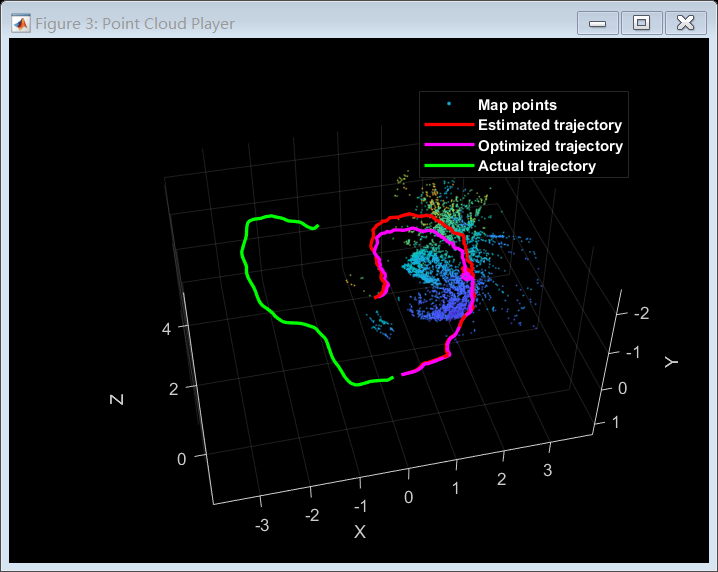


monoSlamOut = helperVisualSLAMCodegen_mex(imageArray);

% Visualize the results
mapPlot = helperVisualizeMonoVisualSlam(monoSlamOut);


function [features, validPoints] = helperDetectAndExtractFeatures(Irgb, ...
    scaleFactor, numLevels, numPoints, varargin)

% In this example, the images are already undistorted. In a general
% workflow, uncomment the following code to undistort the images.
%
% if nargin > 4
%     intrinsics = varargin{1};
% end
% Irgb  = undistortImage(Irgb, intrinsics);

% Detect ORB features
Igray  = im2gray(Irgb);

points = detectORBFeatures(Igray, ScaleFactor=scaleFactor, NumLevels=numLevels);

% Select a subset of features, uniformly distributed throughout the image
points = selectUniform(points, numPoints, size(Igray, 1:2));

% Extract features
[features, validPoints] = extractFeatures(Igray, points);
end

function [H, score, inliersIndex] = helperComputeHomography(matchedPoints1, matchedPoints2)

[H, inliersLogicalIndex] = estgeotform2d( ...
    matchedPoints1, matchedPoints2, "projective", ...
    MaxNumTrials=1e3, MaxDistance=4);

inlierPoints1 = matchedPoints1(inliersLogicalIndex);
inlierPoints2 = matchedPoints2(inliersLogicalIndex);

inliersIndex  = find(inliersLogicalIndex);

locations1 = inlierPoints1.Location;
locations2 = inlierPoints2.Location;
xy1In2     = transformPointsForward(H, locations1);
xy2In1     = transformPointsInverse(H, locations2);
error1in2  = sum((locations2 - xy1In2).^2, 2);
error2in1  = sum((locations1 - xy2In1).^2, 2);

outlierThreshold = 6;

score = sum(max(outlierThreshold-error1in2, 0)) + ...
    sum(max(outlierThreshold-error2in1, 0));
end

function [F, score, inliersIndex] = helperComputeFundamentalMatrix(matchedPoints1, matchedPoints2, intrinsics)

[E, inliersLogicalIndex] = estimateEssentialMatrix( ...
    matchedPoints1, matchedPoints2, intrinsics, MaxNumTrials=1e3, MaxDistance=4);

F = intrinsics.K'\ E /intrinsics.K;

inlierPoints1 = matchedPoints1(inliersLogicalIndex);
inlierPoints2 = matchedPoints2(inliersLogicalIndex);

inliersIndex  = find(inliersLogicalIndex);

locations1    = inlierPoints1.Location;
locations2    = inlierPoints2.Location;

% Distance from points to epipolar line
lineIn1   = epipolarLine(F', locations2);
error2in1 = (sum([locations1, ones(size(locations1, 1),1)].* lineIn1, 2)).^2 ...
    ./ sum(lineIn1(:,1:2).^2, 2);
lineIn2   = epipolarLine(F, locations1);
error1in2 = (sum([locations2, ones(size(locations2, 1),1)].* lineIn2, 2)).^2 ...
    ./ sum(lineIn2(:,1:2).^2, 2);

outlierThreshold = 4;

score = sum(max(outlierThreshold-error1in2, 0)) + ...
    sum(max(outlierThreshold-error2in1, 0));

end

function [isValid, xyzPoints, inlierIdx] = helperTriangulateTwoFrames(...
    pose1, pose2, matchedPoints1, matchedPoints2, intrinsics, minParallax)

camMatrix1 = cameraProjection(intrinsics, pose2extr(pose1));
camMatrix2 = cameraProjection(intrinsics, pose2extr(pose2));

[xyzPoints, reprojectionErrors, isInFront] = triangulate(matchedPoints1, ...
    matchedPoints2, camMatrix1, camMatrix2);

% Filter points by view direction and reprojection error
minReprojError = 1;
inlierIdx  = isInFront & reprojectionErrors < minReprojError;
xyzPoints  = xyzPoints(inlierIdx ,:);

% A good two-view with significant parallax
ray1       = xyzPoints - pose1.Translation;
ray2       = xyzPoints - pose2.Translation;
cosAngle   = sum(ray1 .* ray2, 2) ./ (vecnorm(ray1, 2, 2) .* vecnorm(ray2, 2, 2));

% Check parallax
isValid = all(cosAngle < cosd(minParallax) & cosAngle>0);
end

function mapPointSet = helperUpdateGlobalMap(...
    mapPointSet, vSetKeyFrames, vSetKeyFramesOptim)
%helperUpdateGlobalMap update map points after pose graph optimization
posesOld     = vSetKeyFrames.Views.AbsolutePose;
posesNew     = vSetKeyFramesOptim.Views.AbsolutePose;
positionsOld = mapPointSet.WorldPoints;
positionsNew = positionsOld;
indices     = 1:mapPointSet.Count;

% Update world location of each map point based on the new absolute pose of 
% the corresponding major view
for i = indices
    majorViewIds = mapPointSet.RepresentativeViewId(i);
    poseNew = posesNew(majorViewIds).A;
    tform = affinetform3d(poseNew/posesOld(majorViewIds).A);
    positionsNew(i, :) = transformPointsForward(tform, positionsOld(i, :));
end
mapPointSet = updateWorldPoints(mapPointSet, indices, positionsNew);
end